# Trabajo práctico: Estimación de estados

clear;

## 2) Matriz de observabilidad

El siguiente sistema de suspensión activa se puede modelar como,

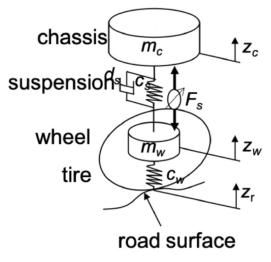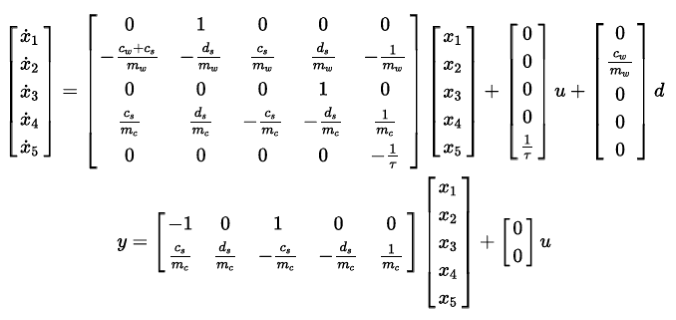

donde $x_{1}$ es la posición de la rueda, $x_{2}$ es la velocidad de la rueda, $x_{3}$ es la posición del chasis, $x_{4}$ es la velocidad del chasis y $x_{5}$ es la fuerza del actuador. $d$ es la perturbación del sistema, la posición de la superficie del terreno.

mc = 401; mw = 48;                  % Kg
ds = 2200; cs = 23000; cw = 250000; % N/m
t = 0.001;                          % s

Se desean evaluar tres escenarios de observabilidad para determinar el o los sensores más convenientes de usar en el modelo.

A = [
    0           1       0       0       0;
    -(cw+cs)/mw -ds/mw  cs/mw   ds/mw   -1/mw;
    0           0       0       1       0;
    cs/mc       ds/mc   -cs/mc  -ds/mc  1/mc;
    0           0       0       0       -1/t];
C = [-1      0       1       0       0];

#### a) ¿Es el sistema observable para la matriz C sumistrada?

Wo = [C; C*A; C*A^2; C*A^3; C*A^4];
disp(rank(Wo));

     5



El sistema es **observable **desde la posición de la rueda y la posición del chasis.

#### b) Si la matriz C es $C = [-1\quad0\quad1\quad0\quad0]$, ¿qué estados se están midiendo a la salida? ¿El sistema es observable?

C = [-1 0 1 0 0];

#### c) Si la matriz C es $C = [1\quad0\quad0\quad0\quad0]$, ¿qué estado se está midiendo? ¿El sistema es observable?

C = [1 0 0 0 0];
Wo = [C; C*A; C*A^2; C*A^3; C*A^4];
disp(rank(Wo));

     5



El sistema es **observable** desde la posición de la rueda.